Hunt for a sensiple LQI solution

Load the Linearised quadcopter+pendulum model

load('bh_SAVED_LIN_PLANT.mat')
size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Control design:

We'll use the approach described by the LQI() function, ie::

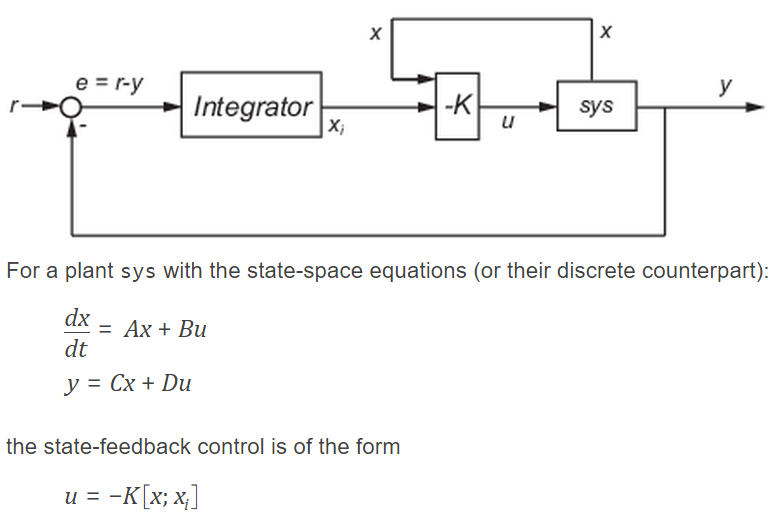

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;


Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

tmp_N  = 1e4;

res_T.tf_is_good   = false;
res_T.K            = [];
res_T.p            = [];
res_T.tf_all_p_neg = false;
res_T.p_first      = 0;
res_T.K_av         = 0;

res_array   = repmat(res_T, [1,tmp_N]);

for gg=1:tmp_N
   try
       [K, p_lqi] = LOC_do_LQI(my_LIN_PLANT, 1, gg, Nx, Ny, Nu);
       res_array(gg).tf_is_good = true;
       res_array(gg).K = K;
       res_array(gg).p = p_lqi;
       if( all( real(p_lqi) < 0 ))
           res_array(gg).tf_all_p_neg = true;           
       end
       res_array(gg).p_first = p_lqi(1);
       
       tmp = abs(K);
       res_array(gg).K_av = mean(tmp(:));
       fprintf('\n .. got one !')
   catch
       
   end
   
end % for


 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. got one !
 .. g

Local Subfunctions only

function [K, p_lqi] = LOC_do_LQI(my_LIN_PLANT, g_Q, g_R, Nx, Ny, Nu)

    tmp = g_Q*[ones(1, Nx+Ny)];
    Q   = diag(tmp); 
    tmp = g_R*[1,1,1,1];
    R = diag(tmp); 
    
    [K,~,~] = lqi(my_LIN_PLANT,Q,R,[]);

    
    A = my_LIN_PLANT.A;
    B = my_LIN_PLANT.B;
    C = my_LIN_PLANT.C;
    
    A_hat = [  A,   zeros(Nx,Ny);
              -C,   zeros(Ny,Ny) ];
      
    B_hat = [ B;
              zeros(Ny,Nu) ];
          
    p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) );
    
end